## Inverse Kinematics

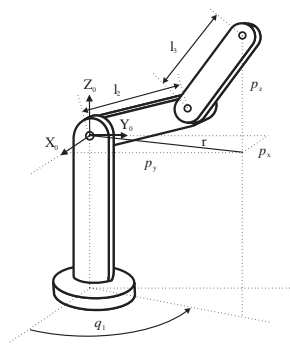

syms px py pz l2 l3 q3 r

% With Geometric Methods
q1 = atan(py/px)

$$q1 = \mathrm{atan}\left(\frac{\mathrm{py}}{\mathrm{px}}\right)$$

r1 = sqrt(py^2 + px^2)

$$r1 = \sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}$$

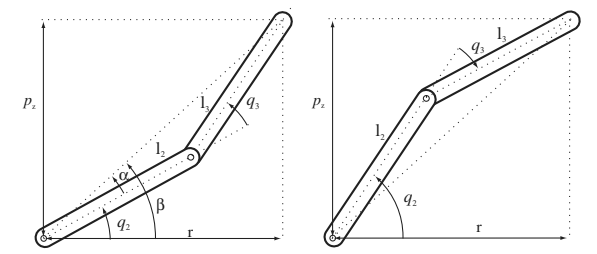

r2 = sqrt(l2^2 + l3^2 + 2*l2*l3*cos(q3) - pz^2)

$$r2 = \sqrt{{l_{2}}^{2}+2\,\cos\left(q_{3}\right)\,l_{2}\,l_{3}+{l_{3}}^{2}-{\mathrm{pz}}^{2}}$$

% r1 = r2
cos_q3 = (px^2 + py^2 + pz^2 - l2^2 - l3^2)/(2*l2*l3)

$$cos\_q3 = \frac{-{l_{2}}^{2}-{l_{3}}^{2}+{\mathrm{px}}^{2}+{\mathrm{py}}^{2}+{\mathrm{pz}}^{2}}{2\,l_{2}\,l_{3}}$$

sen_q3 = sqrt(1 - cos_q3^2)

$$sen\_q3 = \sqrt{1-\frac{{\left(-{l_{2}}^{2}-{l_{3}}^{2}+{\mathrm{px}}^{2}+{\mathrm{py}}^{2}+{\mathrm{pz}}^{2}\right)}^{2}}{4\,{l_{2}}^{2}\,{l_{3}}^{2}}}$$

% Two possible solutions for q3 a) and b)
q3_1 = atan(sen_q3/cos_q3)

$$q3\_1 = \mathrm{atan}\left(\frac{2\,l_{2}\,l_{3}\,\sqrt{1-\frac{{\left(-{l_{2}}^{2}-{l_{3}}^{2}+{\mathrm{px}}^{2}+{\mathrm{py}}^{2}+{\mathrm{pz}}^{2}\right)}^{2}}{4\,{l_{2}}^{2}\,{l_{3}}^{2}}}}{-{l_{2}}^{2}-{l_{3}}^{2}+{\mathrm{px}}^{2}+{\mathrm{py}}^{2}+{\mathrm{pz}}^{2}}\right)$$

q3_2 = atan(-sen_q3/cos_q3)

$$q3\_2 = -\mathrm{atan}\left(\frac{2\,l_{2}\,l_{3}\,\sqrt{1-\frac{{\left(-{l_{2}}^{2}-{l_{3}}^{2}+{\mathrm{px}}^{2}+{\mathrm{py}}^{2}+{\mathrm{pz}}^{2}\right)}^{2}}{4\,{l_{2}}^{2}\,{l_{3}}^{2}}}}{-{l_{2}}^{2}-{l_{3}}^{2}+{\mathrm{px}}^{2}+{\mathrm{py}}^{2}+{\mathrm{pz}}^{2}}\right)$$

% Two possible solutions for beta a) and b)
beta_1 = atan(pz/-r1)

$$beta\_1 = -\mathrm{atan}\left(\frac{\mathrm{pz}}{\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}}\right)$$

beta_2 = atan(pz/r1)

$$beta\_2 = \mathrm{atan}\left(\frac{\mathrm{pz}}{\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}}\right)$$

alpha = atan((l3*sin(q3))/(l2 + l3*cos(q3)))

$$alpha = \mathrm{atan}\left(\frac{l_{3}\,\sin\left(q_{3}\right)}{l_{2}+l_{3}\,\cos\left(q_{3}\right)}\right)$$

% Two possible solutions for q2 a) and b)
q2_1 = beta_1 - alpha

$$q2\_1 = -\mathrm{atan}\left(\frac{\mathrm{pz}}{\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}}\right)-\mathrm{atan}\left(\frac{l_{3}\,\sin\left(q_{3}\right)}{l_{2}+l_{3}\,\cos\left(q_{3}\right)}\right)$$

q2_2 = beta_2 - alpha

$$q2\_2 = \mathrm{atan}\left(\frac{\mathrm{pz}}{\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}}\right)-\mathrm{atan}\left(\frac{l_{3}\,\sin\left(q_{3}\right)}{l_{2}+l_{3}\,\cos\left(q_{3}\right)}\right)$$

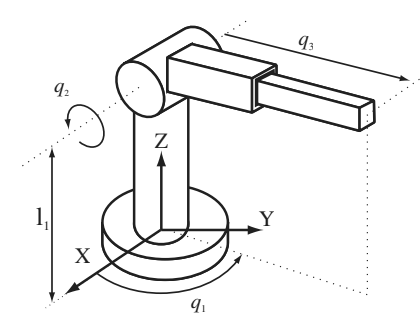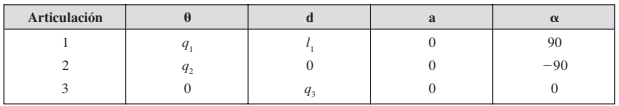

% With Homogeneous Transformation Matrixes
syms q1 q2 q3 l1 nx ny nz ox oy oz ax ay az px py pz

R1 = [cos(q1) -sin(q1) 0; sin(q1) cos(q1) 0; 0 0 1];
T1 = HTM(R1);
p = [0 0 l1]';
T2 = HTM(eye(3), p);
R2 = rotx(90);
T3 = HTM(R2);
A01 = T1 * T2 * T3

$$A01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & \bar{l_{1}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R1 = [cos(q2) -sin(q2) 0; sin(q2) cos(q2) 0; 0 0 1];
T1 = HTM(R1);
R2 = rotx(-90);
T2 = HTM(R2);
A12 = T1 * T2

$$A12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & -\sin\left(q_{2}\right) & 0\\ \sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

p = [0 0 q3]';
A23 = HTM(eye(3), p)

$$A23 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \bar{q_{3}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A02 = A01 * A12

$$A02 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0\\ \sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & \bar{l_{1}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A03 = A02 * A23

$$A03 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\bar{q_{3}}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\bar{q_{3}}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & \bar{l_{1}}+\bar{q_{3}}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% T = A01 * A12 * A23
T = [nx ox ax px; ny oy ay py; nz oz az pz; 0 0 0 1]

$$T = \left(\begin{array}{cccc} \mathrm{nx} & \mathrm{ox} & \mathrm{ax} & \mathrm{px}\\ \mathrm{ny} & \mathrm{oy} & \mathrm{ay} & \mathrm{py}\\ \mathrm{nz} & \mathrm{oz} & \mathrm{az} & \mathrm{pz}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Left expressions based on (q1,...,qk)
T1 = simplify(A01^(-1) * T)

$$T1 = \left(\begin{array}{cccc} \mathrm{nx}\,\cos\left(q_{1}\right)+\mathrm{ny}\,\sin\left(q_{1}\right) & \mathrm{ox}\,\cos\left(q_{1}\right)+\mathrm{oy}\,\sin\left(q_{1}\right) & \mathrm{ax}\,\cos\left(q_{1}\right)+\mathrm{ay}\,\sin\left(q_{1}\right) & \mathrm{px}\,\cos\left(q_{1}\right)+\mathrm{py}\,\sin\left(q_{1}\right)\\ \mathrm{nz} & \mathrm{oz} & \mathrm{az} & \mathrm{pz}-\bar{l_{1}}\\ \mathrm{nx}\,\sin\left(q_{1}\right)-\mathrm{ny}\,\cos\left(q_{1}\right) & \mathrm{ox}\,\sin\left(q_{1}\right)-\mathrm{oy}\,\cos\left(q_{1}\right) & \mathrm{ax}\,\sin\left(q_{1}\right)-\mathrm{ay}\,\cos\left(q_{1}\right) & \mathrm{px}\,\sin\left(q_{1}\right)-\mathrm{py}\,\cos\left(q_{1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T3 = simplify(A12^(-1) *A01^(-1) * T)

$$T3 = \left(\begin{array}{cccc} \mathrm{nz}\,\sin\left(q_{2}\right)+\mathrm{nx}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+\mathrm{ny}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \mathrm{oz}\,\sin\left(q_{2}\right)+\mathrm{ox}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+\mathrm{oy}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \mathrm{az}\,\sin\left(q_{2}\right)+\mathrm{ax}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+\mathrm{ay}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \mathrm{pz}\,\sin\left(q_{2}\right)-\bar{l_{1}}\,\sin\left(q_{2}\right)+\mathrm{px}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+\mathrm{py}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \mathrm{ny}\,\cos\left(q_{1}\right)-\mathrm{nx}\,\sin\left(q_{1}\right) & \mathrm{oy}\,\cos\left(q_{1}\right)-\mathrm{ox}\,\sin\left(q_{1}\right) & \mathrm{ay}\,\cos\left(q_{1}\right)-\mathrm{ax}\,\sin\left(q_{1}\right) & \mathrm{py}\,\cos\left(q_{1}\right)-\mathrm{px}\,\sin\left(q_{1}\right)\\ \mathrm{nz}\,\cos\left(q_{2}\right)-\mathrm{nx}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-\mathrm{ny}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \mathrm{oz}\,\cos\left(q_{2}\right)-\mathrm{ox}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-\mathrm{oy}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \mathrm{az}\,\cos\left(q_{2}\right)-\mathrm{ax}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-\mathrm{ay}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \mathrm{pz}\,\cos\left(q_{2}\right)-\bar{l_{1}}\,\cos\left(q_{2}\right)-\mathrm{px}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-\mathrm{py}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Right expressions based on (qk+1,...,qn)
T2 = A12 * A23

$$T2 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & -\sin\left(q_{2}\right) & -\bar{q_{3}}\,\sin\left(q_{2}\right)\\ \sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & \bar{q_{3}}\,\cos\left(q_{2}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T4 = A23

$$T4 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \bar{q_{3}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% T1(3,4) = T2(3,4)
T1(3,4)

$$ans = \mathrm{px}\,\sin\left(q_{1}\right)-\mathrm{py}\,\cos\left(q_{1}\right)$$

T2(3,4)

$$ans = 0$$

q1 = atan(py/pz)

$$q1 = \mathrm{atan}\left(\frac{\mathrm{py}}{\mathrm{pz}}\right)$$

% T3(1,4) = T4(1,4)
T3(1,4)

$$ans = \mathrm{pz}\,\sin\left(q_{2}\right)-\bar{l_{1}}\,\sin\left(q_{2}\right)+\mathrm{px}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+\mathrm{py}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)$$

T4(1,4)

$$ans = 0$$

q2 = atan(sqrt(px^2 + py^2)/(l1 - pz))      % Solved with T1(3,4)^2 to replace numerator

$$q2 = \mathrm{atan}\left(\frac{\sqrt{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}}{l_{1}-\mathrm{pz}}\right)$$

% T3(3,4) = T4(3,4)
T3(3,4)

$$ans = \mathrm{pz}\,\cos\left(q_{2}\right)-\bar{l_{1}}\,\cos\left(q_{2}\right)-\mathrm{px}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-\mathrm{py}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)$$

T4(3,4)

$$ans = \bar{q_{3}}$$

q3 = cos(q2)*(pz - l1) - sin(q2)*sqrt(px^2 + py^2)

$$q3 = -\frac{l_{1}-\mathrm{pz}}{\sqrt{\frac{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}{{\left(l_{1}-\mathrm{pz}\right)}^{2}}+1}}-\frac{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}{\left(l_{1}-\mathrm{pz}\right)\,\sqrt{\frac{{\mathrm{px}}^{2}+{\mathrm{py}}^{2}}{{\left(l_{1}-\mathrm{pz}\right)}^{2}}+1}}$$